%1a
img_001 = imread('img_001.ppm');
disp(size(img_001))

   605   700     3



%{
(605, 700, 3) corresponds to vector size (row, columns, pages) within this
array. What this means in terms of the image is 605 height of the image in
pixels and 700 is the width of the image in pixels. Then 3 is the amount of
color represention at each pixel. In this case 3 correspondes with the RGB
color format.
%}

%1b
disp(img_001(1:5, 1, 1))

   11
   10
    9
   10
   10



disp(img_001(1:5, 1, 1) .\ 3)

   0
   0
   0
   0
   0



%{
the data type of img_001 currently is unit8 which is a 8 bit unsigned int
that can't be converted into a decimal. Which caused each division to be
set to 0
%}
img_001 = im2double(img_001);
disp(img_001(1:5, 1, 1) .\ 3)

   69.5455
   76.5000
   85.0000
   76.5000
   76.5000



%{
Well its not all zeros but I still don't know if this would be the desited
result. From when we first printed our values they were all aroud 10,
however after going to double precision and deviding by 3 all the value are
around 70 which obivoulsly doesn't seem right. We should be seeing values
around 3.
%}

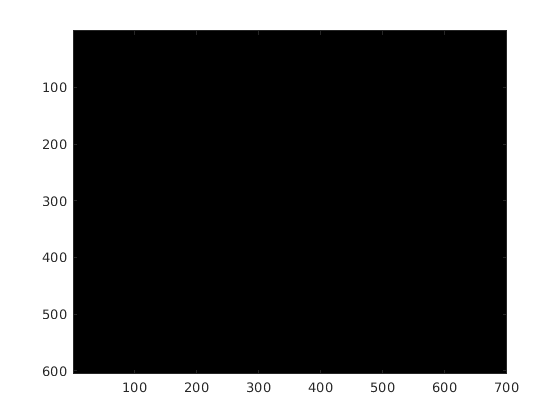

%1c
colormap("gray");
image(img_001(:,:,2))

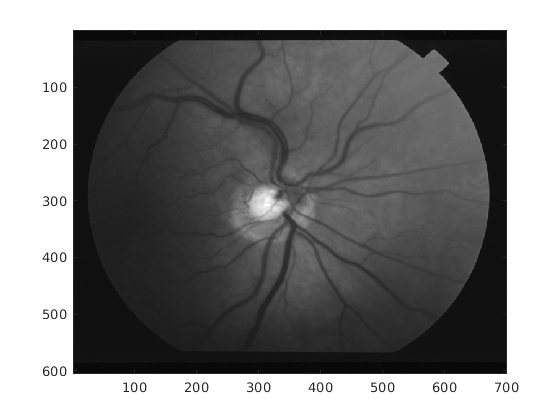

imagesc(img_001(:,:,2))

%{
The first image displayed using image() is pure black however when we use
imagesc() we can see a detailed image. This is because image() by default
using a direct color mapping which doesn't utlize the full color range,
while imagesc() uses a scaled mapping which will fit your pixel values to
use the entire colormap range.
%}

%2
img1 = dicomread('series-1/image-000361.dcm')

'dicomread' requires Image Processing Toolbox.

img2 = dicoread('series-1/image-000362.dcm')
img3 = dicoread('series-1/image-000363.dcm')